# standardize card image

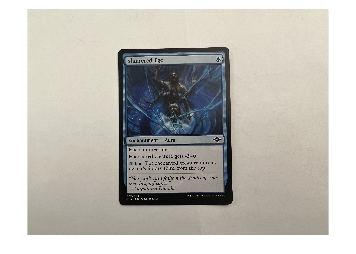

realImg = imread("shattered.jpg");
ogImg = realImg;
figure;
imshow(realImg);

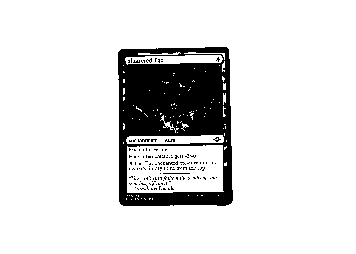


realImg = rgb2gray(realImg);
realImg = medfilt2(realImg);
realImg = imbinarize(realImg,graythresh(realImg));

% % Apply edge detection to obtain binary edges
% edges = edge(realImg, 'Canny'); % You can choose other edge detection methods as well
% 
% % Multiply the binary edge map with the original image to extract only the contour pixels
% contourImage = realImg;
% contourImage(repmat(~edges, [1, 1, size(realImg, 3)])) = 1; % Set non-edge pixels to zero
% 
% % Display the original image and the contour image side by side
% subplot(1,2,1);
% imshow(realImg);
% title('Original Image');
% subplot(1,2,2);
% imshow(contourImage);
% title('Contours Only');


% % Obtain the boundary coordinates using bwboundaries function
% boundaries = bwboundaries(edges);
% 
% % Display the original image
% imshow(realImg);
% hold on;
% 
% % Plot the contour points on top of the original image
% for k = 1:length(boundaries)
%     boundary = boundaries{k};
%     
%     plot(boundary(:, 2), boundary(:, 1), 'r', 'LineWidth', 2); 
% end


[h,l,t] = hough(edge(realImg,"sobel"));
peaks = houghpeaks(h,1);
lines = houghlines(edge(realImg,"sobel"),l,t,peaks);

angle = atan2(lines(1).point2(2)-lines(1).point1(2),lines(1).point2(1)-lines(1).point1(1));
corrected = imrotate(realImg,rad2deg(angle)-90,'bilinear','crop');

figure;
imshow(corrected);

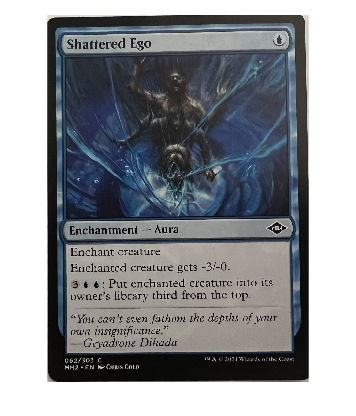


[r,c] = size(corrected);


northmost = r;
southmost = 1;
westmost = c;
eastmost = 1;

for i=r/2-1:r/2+1
    for j=1:c
        if corrected(i,j) == 0
            if j < westmost
                westmost = j;
            end
            if j > eastmost
                eastmost = j;
            end
        end
    end
end

for i=r/2-1:r/2+1
    for j=c:1
        if corrected(i,j) == 0
            if j < eastmost
                eastmost = j;
            end
        end
    end
end

for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i < northmost
                northmost = i;
             
            end
        end
    end
end


for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i > southmost
                southmost = i;
               
            end
        end
    end
end

cropRect = [westmost northmost (eastmost - westmost) (southmost - northmost)];
ogImg = imrotate(ogImg,rad2deg(angle)-90,'bilinear','crop');
croppedImg = imcrop(ogImg,cropRect);
figure;
imshow(croppedImg);

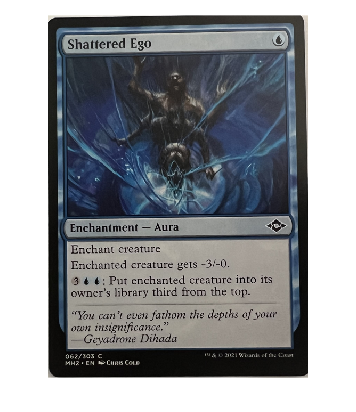


% get
test = imread("https://cards.scryfall.io/art_crop/front/1/4/1465ca9e-a997-4b8c-9677-6c7961f67eba.jpg?1562628773");

% queries
% color
% text
card = croppedImg;
normalSize = [680 488];
card = imresize(card, normalSize);
imshow(card);

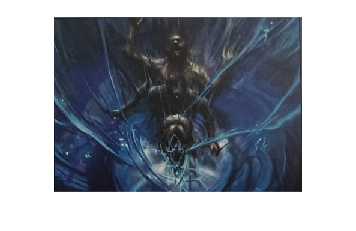

card = imcrop(card, cropRect1);
imshow(card)


artCropSize = [291 413];
%[card1, cropRect1] = imcrop(card);

% OCR test
 text = ocr(croppedImg);
 disp(text.Text);

Enchantment —

% Enchant reature
 Enchanted creature gets -3/-0.

“.1
3 6 6 : Put enchanted creature into its
owner’s library third from the top.

“'3

“Yb; can ’r even fathom the depths of your

own z'nsignzficance.”
—Geyadrone Dzhada

062/303 C -“<\~ 2U2l\\'x7;nr».|<ut‘Il1c <:...m
MH2 - EN r'.>Cums Com

*  rd




%croppedText = imcrop(croppedImg);
%text = ocr(croppedText);
disp(text.Text);

Enchantment —

% Enchant reature
 Enchanted creature gets -3/-0.

“.1
3 6 6 : Put enchanted creature into its
owner’s library third from the top.

“'3

“Yb; can ’r even fathom the depths of your

own z'nsignzficance.”
—Geyadrone Dzhada

062/303 C -“<\~ 2U2l\\'x7;nr».|<ut‘Il1c <:...m
MH2 - EN r'.>Cums Com

*  rd




disp(text.Words(1));

    {'Enchantment'}



disp(text.Words(3));

    {'%'}



figure;
%croppedName = imcrop(croppedImg);
%text = ocr(croppedName);
disp(text.Text);

Enchantment —

% Enchant reature
 Enchanted creature gets -3/-0.

“.1
3 6 6 : Put enchanted creature into its
owner’s library third from the top.

“'3

“Yb; can ’r even fathom the depths of your

own z'nsignzficance.”
—Geyadrone Dzhada

062/303 C -“<\~ 2U2l\\'x7;nr».|<ut‘Il1c <:...m
MH2 - EN r'.>Cums Com

*  rd





%query = sprintf('https://api.scryfall.com/cards/%s/46',text.Words(3));
% query = ['https://api.scryfall.com/cards/', text.Words(3), '/46'];
% query = join(query);

%resultObj = webread(query);
%result = imread(resultObj.image_uris.normal);
%imshow(result);

## dct hashing entire json

jsonStr = fileread('dmuset_artcrop.json');
jsonData = jsondecode(jsonStr);

% creating temp files for storage
%tempCard = imread(cell2mat(jsonData(1)));
%gray_card = rgb2gray(tempCard);
num_coeff = 100;
hash_array = zeros(length(jsonData), num_coeff*num_coeff);

hash_map = containers.Map;

for i=1:length(jsonData)
    tempCard = imread(cell2mat(jsonData(i)));
    gray_card = rgb2gray(tempCard);
    % INCLUDE LINE BELOW FOR 
    %gray_card = imcrop(gray_card, cropRect1);
    gray_card = imresize(gray_card, artCropSize);
    %gray_card = imcrop(gray_card, [130.5 268.5 1505. 1305]);
    % Apply DCT
    dct_img = dct2(gray_card);

    % Extract the high-frequency components
    num_coeffs = num_coeff;
    high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);

    % Generate the hash
    threshold = mean(high_coeffs(:));
    hash = high_coeffs > threshold;
    hash = reshape(hash, 1, []);

    % Store the hash in the hash array
    hash_array(i,:) = hash;
    cell2mat(jsonData(i));
    hash_str = sprintf('%d', hash);
    hash_map(hash_str) = cell2mat(jsonData(i));
end
save('hash_map.mat', 'hash_map');
save('hash.mat', 'hash_array');

## Get answer

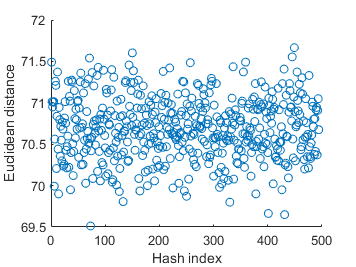

% Choose two hashes to compare (e.g., hashes 1 and 2)
%hash1 = hash_array(1,:);
%hash2 = hash_array(2,:);

% Compute the Hamming distance
%hamming_dist = sum(xor(hash1, hash2));

load('hash.mat');
load('hash_map.mat')
[r,c] = size(hash_array);

% Choose two hashes to compare (e.g., hashes 1 and 2)
hash1 = hash_array(1,:);
theHash = zeros(2500);

lowestDist = 100000;

%Get card to compare
tempCard = card;
gray_card = rgb2gray(tempCard);
% Apply DCT
dct_img = dct2(gray_card);
% Extract the high-frequency components
num_coeffs = num_coeff;
high_coeffs = dct_img(2:num_coeffs+1, 2:num_coeffs+1);
% Generate the hash
threshold = mean(high_coeffs(:));
hash = high_coeffs > threshold;
hash1 = reshape(hash, 1, []);

distance_values=[];
% iterate through the hash_array
for i=1:r
    hash2 = hash_array(i,:);
    % Compute the Hamming distance
    hamming_dist = sum(xor(hash1, hash2));
    % Compute the Euclidean distance
    euclidean_dist = pdist([hash1; hash2], 'euclidean');
    distance_values= [distance_values euclidean_dist];
    if euclidean_dist < lowestDist
        lowestDist = euclidean_dist;
        theHash = hash2;
    end
end


figure;
scatter(1:r, distance_values);
xlabel('Hash index');
ylabel('Euclidean distance');

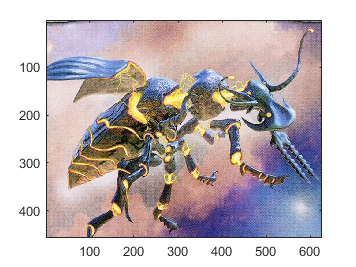


hashKey = sprintf('%d', hash_array(193,:));
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

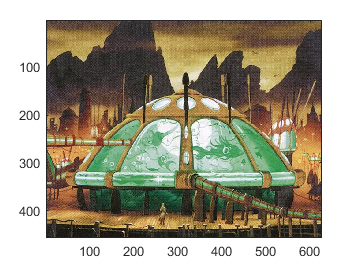


hashKey = sprintf('%d', theHash);
cardURL = hash_map(hashKey);
cardFinalImage = imread(cardURL);
imagesc(cardFinalImage);

## set symbol hash

%[im,rect] = imcrop(cardFinalImage)


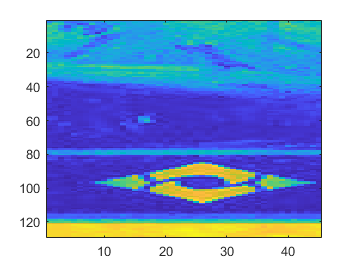

hard_evidence = imread("https://cards.scryfall.io/normal/front/5/0/501599d6-1072-4124-b05d-01f96de153f3.jpg?1626094482");
grist = imread("https://cards.scryfall.io/normal/front/6/9/69af2825-18c2-4463-b6ba-42eaa070ccc1.jpg?1626098484");
brainstone = imread("https://cards.scryfall.io/normal/front/8/e/8ef23258-511f-43f8-b84f-bd2256b5c86b.jpg?1626103568");
suspend_ext = imread("https://cards.scryfall.io/normal/front/f/2/f2b39f1d-6d8b-4d5d-a956-094de5c26ba8.jpg?1631580848");
damn_ext = imread("https://cards.scryfall.io/normal/front/4/0/402060d4-10d6-4cee-aa8b-cd083bf5df43.jpg?1631580868");

%mh2 = imread("https://svgs.scryfall.io/sets/mh2.svg");
%aer = imread("https://svgs.scryfall.io/sets/aer.svg");
%imshow(imgData)


image = damn_ext;
set_crop = imcrop(image,[404.51 337.51 44.98 128.98]);
set_crop = rgb2gray(set_crop);
imagesc(set_crop);